# Atividade 3 - Série Exponencial de Fourier

## Boas Práticas

clear;                %%% limpando as variáveis
close all;            %%% fechando todas as figuras
clc;                  %%% limpando a tela

## Exercício 1:

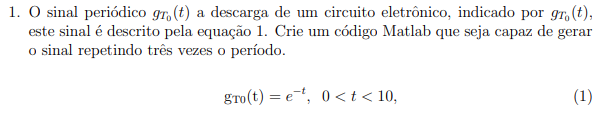

### Determinação dos Parâmetros

T0 = 10;                            %%% Período
t_total = 0:0.01:3*T0;              %%% Vetor de tempo para três períodos

### Sinal g_T0(t)

g = exp(-mod(t_total, T0))         %%% repete o sinal a cada período

g =     1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250    0.6188    0.6126


### Plot do sinal

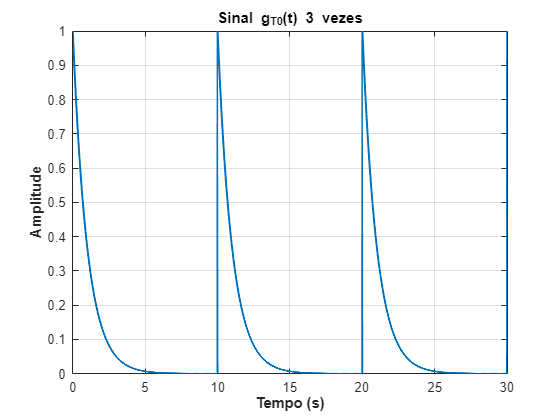

plot(t_total, g, 'LineWidth', 1.5);         %%% Plot do sinal 3 vezes 
title('Sinal g_T_0(t) 3 vezes');            %%% Título do gráfico
xlabel('Tempo (s)', 'FontWeight', 'bold');  %%% Título do eixo x
ylabel('Amplitude', 'FontWeight', 'bold');  %%% Título do eixo y
grid on;                                    %%% Exibir com o quadriculado

## Exercício 2

### Definição das variáveis simbólicas

syms t                                                  %%% Variável simbólica                                        

### Cálculo simbólico da potência de gT0(t)

g_simbolico = exp(-t)                                   %%% Função g(t)

$$g\_simbolico = {\mathrm{e}}^{-t}$$

Pg_simbolico = (1/T0) * int(g_simbolico^2, t, 0, T0)    %%% Potência de forma simbólica

$$Pg\_simbolico = \frac{1}{20}-\frac{{\mathrm{e}}^{-20}}{20}$$

### Cálculo numérico

Pg_num = eval(Pg_simbolico)                             %%% Potência de forma numérica

Pg_num = 0.0500

## Exercício 3

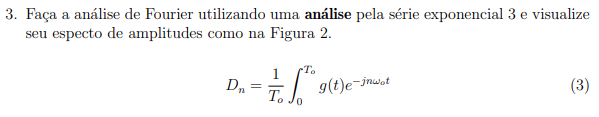

### Parâmetros da série de Fourier

syms n            %%% Variável simbólica
w0 = 2*pi/T0;     %%% Frequência angular

### Calculo simbolico de Dn

Dn = (1/T0) * int(exp(-t)*exp(-1i*n*w0*t), t, 0, T0)     %%% Fórmula de Dn

$$Dn = -\frac{{\mathrm{e}}^{-10}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{2\,\left(5+\pi \,n\,\mathrm{i}\right)}$$

### Calculo numérico de Dn

N = 10;                             %%% Número de harmônicas positivas e negativas
n = -N:1:N;                         %%% Vetor para percorrer as harmônicas


freq = linspace(-1,1, 2*N + 1);     %%% Vetor de frequência positivas e negativas, mais a central
amplitudes = abs(eval(Dn))          %%% Valores das amplitudes 

amplitudes =     0.0157    0.0174    0.0195    0.0222    0.0256    0.0303    0.0370    0.0469    0.0623    0.0847    0.1000    0.0847    0.0623    0.0469    0.0370    0.0303    0.0256    0.0222    0.0195    0.0174    0.0157


### Plotagem

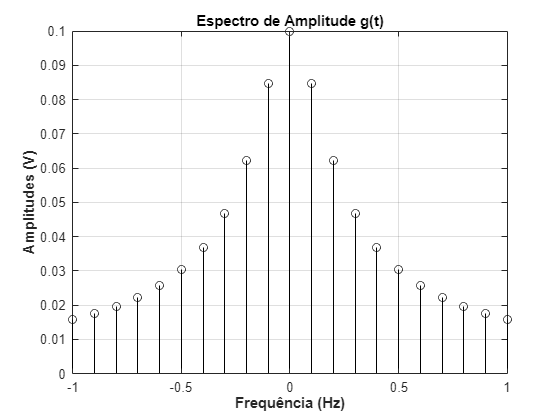

figure;
stem (freq, amplitudes, "Color", "k");            %%% Função para pegar as amplitudes e plotar

title('Espectro de Amplitude g(t)');              %%% Título do gráfico
xlabel('Frequência (Hz)', 'FontWeight', 'bold');  %%% Título do eixo x
ylabel('Amplitudes (V)', 'FontWeight', 'bold');   %%% Título do eixo y
grid on;                                          %%% Quadriculado
axis([-1 1 0 0.1])                                %%% Intervalo

## Exercício 4

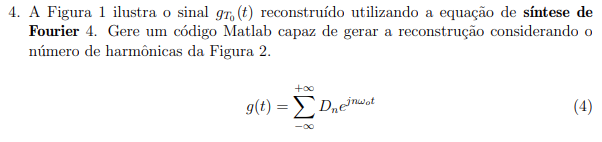

### Definição das variáveis

tempo = 0:1e-3:30;                    %%% Vetor de tempo
g_original = exp(-mod(tempo, T0));    %%% Sinal periódico original
Dn_plot = eval(Dn);                   %%% Valores numéricos de Dn

### Soma de termos da série exponencial de Fourier

aux = zeros(size(tempo)); %%% Variável para otimizar 

for k = 1:length(n)
    aux = aux + Dn_plot(k)*exp(1i * n(k) * w0 .* tempo);
end

g_reconstrucao = real(aux);  %%% Parte real

### Plotagem

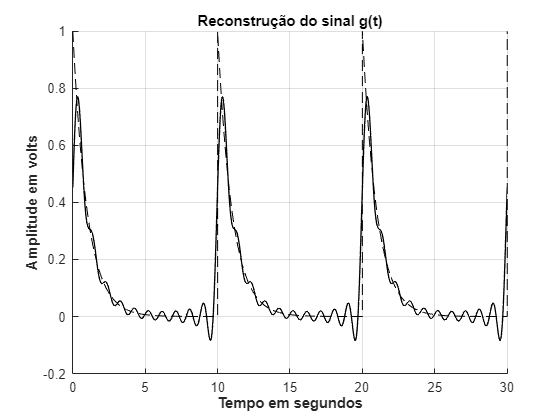

figure
hold on;                                                    %%% Segura os gráficos
plot(tempo, g_original, "Color", 'k', 'LineStyle', '--');   %%% Sinal original
plot(tempo, g_reconstrucao, 'LineWidth', 1, "Color", 'k');  %%% Sinal original
title('Reconstrução do sinal g(t)', 'FontWeight', 'bold');  %%% Título do gráfico
xlabel('Tempo em segundos', 'FontWeight', 'bold');          %%% Título do eixo x 
ylabel('Amplitude em volts', 'FontWeight', 'bold');         %%% Título do eixo y
grid on;                                                    %%% Exibir com quadriculado 
hold off;                                                   %%% Soltar os gráficos

## Exercício 05 - Obtenção, Análise e Reconstrução do Sinal fT0(t):

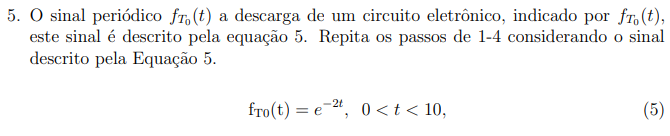

### Definição das Variáveis

T0 = 10;                  %%% Períodos
tempo = 0:1e-3:30;        %%% Vetor de tempo

### Cálculo do Sinal Original

t_mod = mod(tempo, T0);          %%% Calculo do tempo para todos os períodos

fT0 = exp(-2*t_mod);             %%% Função sendo aplicada a todo vetor 

### Plotagem

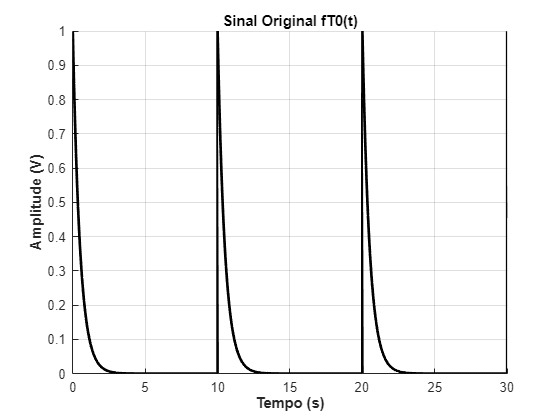

figure; 
hold on;                                                    %%% Segura os gráficos

plot(tempo, fT0,'LineWidth',2,'Color','k');                 %%% Sinal original
title('Sinal Original fT0(t)');                             %%% Título do gráfico
xlabel('Tempo (s)','FontWeight','bold');                    %%% Título do eixo x
ylabel('Amplitude (V)','FontWeight','bold');                %%% Título do eixo y
grid on;                                                    %%% Exibir com quadriculado 
hold off;                                                   %%% Soltar os gráficos

### Potência de fT0(t)

p2 = (1/T0)*int((exp(-2*t))^2,t,0,10) %%% Potência (simbólica) de fT0(t)

$$p2 = \frac{1}{40}-\frac{{\mathrm{e}}^{-40}}{40}$$

P2 = eval(p2)                         %%% Potência numérica

P2 = 0.0250

### Espectro de Amplitudes

Dn2 = (1/T0)*int(exp(-2*t)*exp(-1j*n*w0*t),t,0,10);  %%% Coeficientes Dn2
amplitudes2 = abs(eval(Dn2));                        %%% Módulo dos coeficientes

#### Plotagem

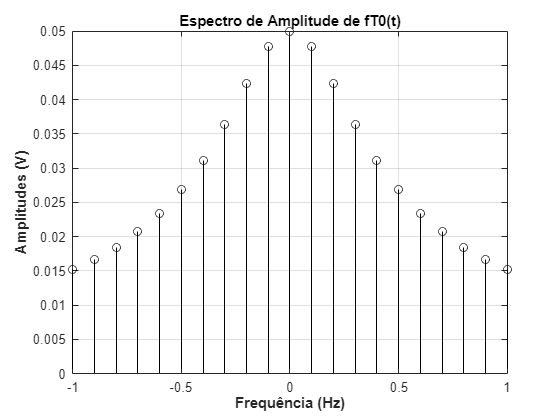

figure;
stem (freq, amplitudes2, "Color", "k");           %%% Função para pegar as amplitudes e plotar

title('Espectro de Amplitude de fT0(t)'); 
xlabel('Frequência (Hz)','FontWeight','bold');    %%% Título do eixo x
ylabel('Amplitudes (V)','FontWeight','bold');     %%% Título do eixo y
grid on;                                          %%% Quadriculado     
axis([-1 1 0 0.05])                               %%% Intervalo

## Síntese do sinal fT0(t)

Dn2_plot = eval(Dn2);                                       %%% Avalia numericamente os coeficientes Dn2 (vetor coluna ou linha)
aux2 = sum(Dn2_plot(:) .* exp(1j * n(:) * w0 * tempo), 1);  %%% Soma vetorizada dos termos da série de Fourier

#### Plotagem

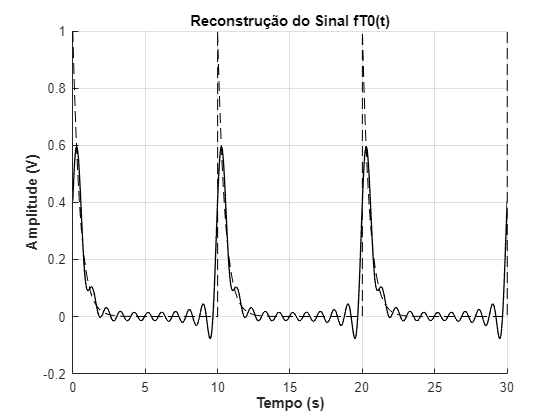

figure; 
hold on;                                                      %%% Mantém os plots
plot(tempo, fT0, 'k--');                                      %%% Plota o sinal original
plot(tempo, real(aux2), 'k', 'LineWidth', 1);                 %%% Plota o sinal reconstruído

title('Reconstrução do Sinal fT0(t)', 'FontWeight', 'bold');  %%% Define o título do gráfico
xlabel('Tempo (s)', 'FontWeight', 'bold');                    %%% Título do eixo x
ylabel('Amplitude (V)', 'FontWeight', 'bold');                %%% Título do eixo y
grid on;                                                      %%% Quadriculado
hold off;                                                     %%% Solta os gráficos

## Exercício 6

### Definição das Variáveis

T0 = 10;                                  %%% Período 
tempo = 0:1e-3:30;                        %%% Vetor de tempo 

### Construção do sinal fT0(t)

t_mod = mod(tempo, T0);                   %%% Calculo do tempo de cada período
fT0 = exp(-2*t_mod);                      %%% Função fT0
gT0 = exp(-t_mod);                        %%% Função gT0
hT0 = fT0 + gT0;                          %%% Soma dos sinais fT0(t) e gT0(t)

### Plot do sinal original hT0(t)

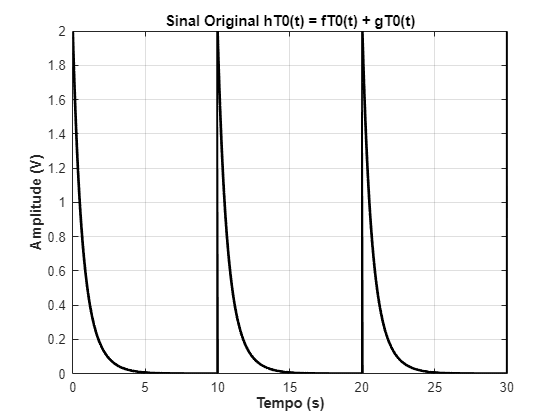

figure;
plot(tempo, hT0, 'LineWidth', 2, 'Color', 'k');                             %%% Plota hT0(t)
title('Sinal Original hT0(t) = fT0(t) + gT0(t)', 'FontWeight', 'bold');     %%% Título do gráfico
xlabel('Tempo (s)', 'FontWeight', 'bold');                                  %%% Título do eixo x
ylabel('Amplitude (V)', 'FontWeight', 'bold');                              %%% Título do eixo y
grid on;                                                                    %%% Quadriculado

### Potência de hT0(t)

syms t;                                           %%% Variável simbólica
p3 = (1/T0)*int((exp(-2*t)+exp(-t))^2, t, 0, T0)  %%% Potência simbólica de hT0(t)

$$p3 = \frac{17}{120}-\frac{{\mathrm{e}}^{-40}\,\left(8\,{\mathrm{e}}^{10}+6\,{\mathrm{e}}^{20}+3\right)}{120}$$

P3 = eval(p3)                                     %%% Potência numericamente de hT0(t)

P3 = 0.1417

### Espectro de Amplitudes

syms n;                                                           %%% Variável simbólica 
w0 = 2*pi/T0;                                                     %%% Define a frequência angular fundamental
Dn3 = (1/T0)*int((exp(-2*t)+exp(-t))*exp(-1j*n*w0*t), t, 0, T0);  %%% Fórmula dos coeficientes Dn3

### Coeficientes Dn3

N = 10;                                   %%% Harmônicas
n = -N:1:N;                               %%% Vetor de harmônicos
Dn3_plot = eval(Dn3);                     %%% Valor numérico de Dn3
amplitudes3 = abs(Dn3_plot);              %%% Calcula o módulo dos coeficientes
freq = linspace(-N/T0, N/T0, 2*N+1);      %%% Frequências 

### Plotagem 1

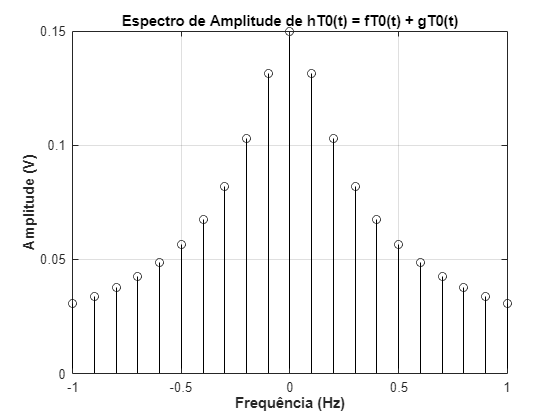

figure;
stem(freq, amplitudes3, "Color", "k");                                             %%% Plota o espectro de amplitude com hastes em preto

title('Espectro de Amplitude de hT0(t) = fT0(t) + gT0(t)', 'FontWeight', 'bold');  %%% Título do gráfico
xlabel('Frequência (Hz)', 'FontWeight', 'bold');                                   %%% Título do eixo x
ylabel('Amplitude (V)', 'FontWeight', 'bold');                                     %%% título do eixo y
grid on;                                                                           %%% Quadriculado
axis([-1 1 0 0.15]);

### Síntese do sinal 

aux3 = sum(Dn3_plot(:) .* exp(1j * n(:) * w0 * tempo), 1);  %%% Soma dos termos da série
h_reconstrucao = real(aux3);                                %%% Parte real da síntese

### Plotagem 2

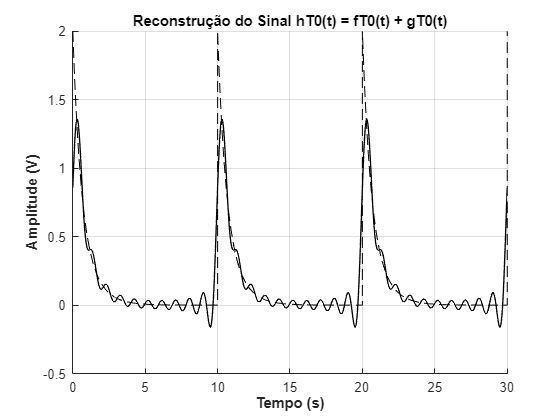

figure;
hold on;                                                                        %%% Mantém os gráficos 
plot(tempo, hT0, "k--");                                                        %%% Plota o sinal original hT0(t) 
plot(tempo, h_reconstrucao, 'LineWidth', 1, "Color", 'k');                      %%% Plota o sinal reconstruído

title('Reconstrução do Sinal hT0(t) = fT0(t) + gT0(t)', 'FontWeight', 'bold');  %%% Título do gráfico
xlabel('Tempo (s)', 'FontWeight', 'bold');                                      %%% Título do eixo x
ylabel('Amplitude (V)', 'FontWeight', 'bold');                                  %%% título do eixo y
hold off;                                                                       %%% Solta os gráficos
grid on;                                                                        %%% Quadriculado

## Conclusão

De fato a conclusão que se chega é que, uma vez obtido os espectros de amplitude e as sínteses dos sinais $g_{T0}$ e $f_{T0}$, pode-se obter os mesmos resultados fazendo apenas a soma, e não tendo que refazer todos os cálculos para gerar um novo espectro e uma nova síntese, essa conclusão será demonstrada abaixo:

### Plot da soma dos espectros de fT0(t) e gT0(t)

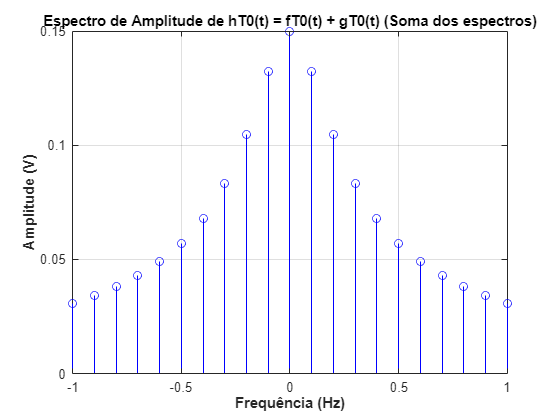

figure;
stem(freq, amplitudes + amplitudes2, "Color", "b");  
                              
title('Espectro de Amplitude de hT0(t) = fT0(t) + gT0(t) (Soma dos espectros)', 'FontWeight', 'bold');
xlabel('Frequência (Hz)', 'FontWeight', 'bold'); 
ylabel('Amplitude (V)', 'FontWeight', 'bold');
grid on; 
axis([-1 1 0 0.15]);

### Plot da síntese obtida pela soma das sínteses individuais de fT0(t) e gT0(t)

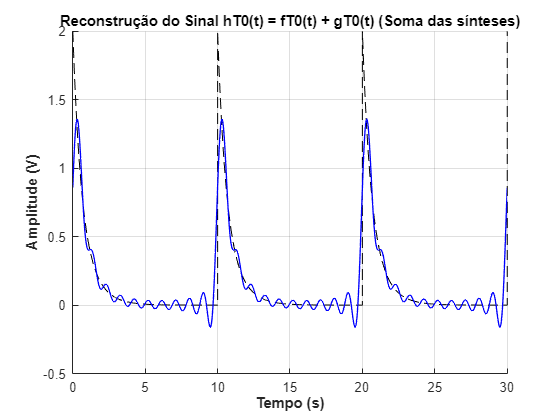

figure;
hold on;
plot(tempo, hT0, "k--");
plot(tempo, real(aux + aux2), 'LineWidth', 1, "Color", 'b');

title('Reconstrução do Sinal hT0(t) = fT0(t) + gT0(t) (Soma das sínteses)', 'FontWeight', 'bold');
xlabel('Tempo (s)', 'FontWeight', 'bold');
ylabel('Amplitude (V)', 'FontWeight', 'bold'); 
hold off;
grid on;